# Testing the Purturbation Method

Version Info:

Version 1:

(03/02/2026)

## Clear variables between Runs:

clear % clear variables and everything
clc % clear command window

## Set up Save Path

saveDir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Saved_Results';
%if ~exist(saveDir, 'dir')
%    mkdir(saveDir);
%end

## Select Parameters:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
params.freq = 3e9;
params.lambda = 3e8 / params.freq; 
lambda = params.lambda; 
%params.N = 9;
%N = params.N; %Number of drones

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate

## Generate Initial Configuration (To serve as a starting point for our optimization)

% Initialize nieve 9-element "double cross" coordinates
%x = [0 0 0 0.5*lambda -0.5*lambda 0.5*lambda -0.5*lambda lambda -lambda]';
%y = [0 0.5*lambda -0.5*lambda 0 0 0.5*lambda -0.5*lambda lambda -lambda]';
    
% Initialize Daniil's "good" version of the 9-element "double cross" coordinates
%z = zeros(1,N);
%d1 = 0.422 * lambda;
%d2 = 0.554 * lambda;
%[x,y] = d1d2Convert(d1,d2,N);

% Initialize Eric's 'better' version (specifically for 120 degrees)
%d1 = 0.049553426571036;
%d2 = 0.049015017974167;
%[x,y] = d1d2Convert(d1,d2,N);

% Initialize test version with two elements
%x = [0 lambda/2];
%y = [0 0];

% Eric's optimal "5 element setup"
%x = [0, 0.019598444542977, 0, -0.019598444542977, 0];
%y = [0, 0, 0.019598444542977, 0, -0.019598444542977];


% Initialize Eric's "true correct and optimal 9 element ones" from the meeting with everybody
% (double cross with two radii)
%x = [0	-0.042211347450806	0.042211347450806	0	0	0.039173549691350	-0.039173549691350	-0.039173549691350	0.039173549691350];
%y = [0	0	0	0.042211347450806	-0.042211347450806	0.039173549691350	0.039173549691350	-0.039173549691350	-0.039173549691350];

% Initialize Eric's 13 element coordinates
%x = [0 0.0150 0.0075 -0.0075 -0.0150 -0.0075 0.0075 0.0866 0.0000 -0.0866 -0.0866 -0.0000 0.0866];
%y = [0 0 0.0130 0.0130 0.0000 -0.0130 -0.0130 0.0500 0.1000 0.0500 -0.0500 -0.1000 -0.0500];

% Initialize test version without center emitter
%x(1) = [];
%y(1) = [];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Compare 5, 9(ring), 13 element cases

% Eric's optimal "5 element setup"
%x = [0, 0.019598444542977, 0, -0.019598444542977, 0];
%y = [0, 0, 0.019598444542977, 0, -0.019598444542977];

% Initialize "All on one ring" version of the 9-element "double cross" coordinates
% This is equivalent to an regular octogon with radius 0.05 starting at (0.05,0).
%z = zeros(1,N);
% for 5 elements
%d1 = 0.019598444542977;
%d2 = 0.019598444542977;
% for 9 elements
%d1 = 0.5 * lambda;
%d2 = 0.5 * lambda;
d1 = 0.04880;
d2 = 0.04880;
[x,y] = d1d2Convert(d1,d2,9) %Change to 5,9,13 apropriatly

x =          0    0.0488    0.0000   -0.0488   -0.0000    0.0345   -0.0345   -0.0345    0.0345


y =          0         0    0.0488    0.0000   -0.0488    0.0345    0.0345   -0.0345   -0.0345



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Eric's special calculated emitter positions (2/25/26)

% N=5
%x = [0	0.019598452160414	0.000000000000000	-0.019598452160414	-0.000000000000000];
%y = [0	0	0.019598452160414	0.000000000000000	-0.019598452160414];

%N=9
%x = [0	0.0505	0.0357	0.0000	-0.0357	-0.0505	-0.0357	-0.0000	0.0357];
%y = [0	0	0.035713085910583	0.050505930448942	0.035713085910583	0.000000000000000	-0.035713085910583	-0.050505930448942	-0.035713085910583];

%N=13
%x = [0	0.050600639149324	0.043821438951044	0.025300319574662	0.000000000000000	-0.025300319574662	-0.043821438951044	-0.050600639149324	-0.043821438951044	-0.025300319574662	-0.000000000000000	0.025300319574662	0.043821438951044];
%y = [0	0	0.025300319574662	0.043821438951044	0.050600639149324	0.043821438951044	0.025300319574662	0.000000000000000	-0.025300319574662	-0.043821438951044	-0.050600639149324	-0.043821438951044	-0.025300319574662];

%N=17
%x = [0	0.050600865112511	0.046749103604814	0.035780214854963	0.019364112741899	0.000000000000000	-0.019364112741899	-0.035780214854963	-0.046749103604814	-0.050600865112511	-0.046749103604814	-0.035780214854963	-0.019364112741899	-0.000000000000000	0.019364112741899	0.035780214854963	0.046749103604814];
%y = [0	0	0.019364112741899	0.035780214854963	0.046749103604814	0.050600865112511	0.046749103604814	0.035780214854963	0.019364112741899	0.000000000000000	-0.019364112741899	-0.035780214854963	-0.046749103604814	-0.050600865112511	-0.046749103604814	-0.035780214854963	-0.019364112741899];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Test multiples of geometric pattern
%x = (1.1)*x;
%y = (1.1)*y;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Test Single emitter for 9 elements
%A_single = [1, 1, 0, 0, 0, 0, 0, 0, 0];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Test Linear emitter for 9 elements
%x = linspace(-4,4,9).*(0.5*lambda);
%y = zeros(1,9);

## Set-up and Run the One-Beam version of the Algorithm

[Init] 4 sidelobes above -20.0 dB
[Epoch   1] 3 sidelobes above -20.0 dB | max = -9.63 dB
[Epoch   2] 2 sidelobes above -20.0 dB | max = -12.29 dB
[Epoch   3] 2 sidelobes above -20.0 dB | max = -12.54 dB
[Epoch   4] 1 sidelobes above -20.0 dB | max = -17.19 dB
[Epoch   5] 1 sidelobes above -20.0 dB | max = -18.42 dB
[Epoch   6] 1 sidelobes above -20.0 dB | max = -19.57 dB
[Epoch   7] 0 sidelobes above -20.0 dB | max = NaN dB


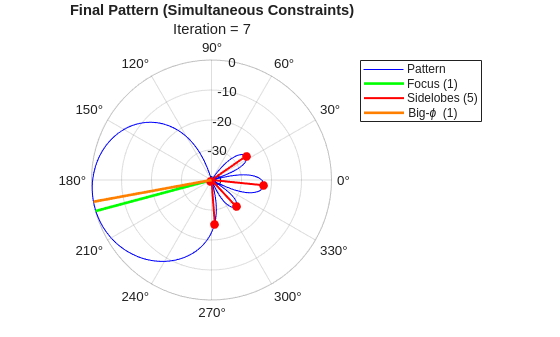

%% Start Function
Max_iter = 500; %The algithm goes to step maxiter
eps_dB = -20;
phi_0 = deg2rad(195);
null_phi_list = deg2rad([]);
save_plots = false;
save_final_plot = true;
cone_rad = deg2rad(30);

results = perturb_method(50, -20, x, y, phi_0, ...                                                                                
      'simultaneous', true, 'phi_null', pi/3, ...          
      'show_final', true, 'verbose', true);

[Init] 4 sidelobes above -20.0 dB
[Epoch   1] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch   2] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch   3] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch   4] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch   5] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch   6] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch   7] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch   8] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch   9] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch  10] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch  11] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch  12] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch  13] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch  14] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch  15] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch  16] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch  17] 4 sidelobes above -20.0 dB | max = -9.45 dB
[Epoch  18] 4 

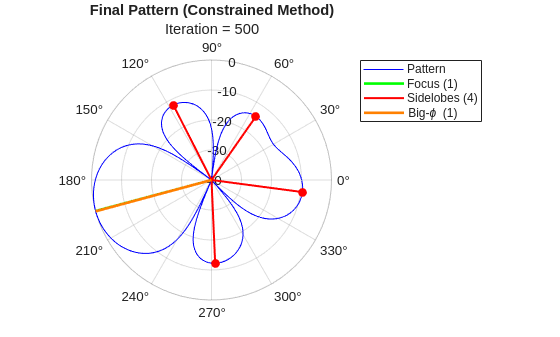


Max_iter = 500;
eps_dB   = -20;
results = perturb_method(Max_iter, eps_dB, x, y, phi_0, ...
    'constrained', true, ...
    'full_loop', false, ...
    'show_final', true, ...
    'verbose', true);

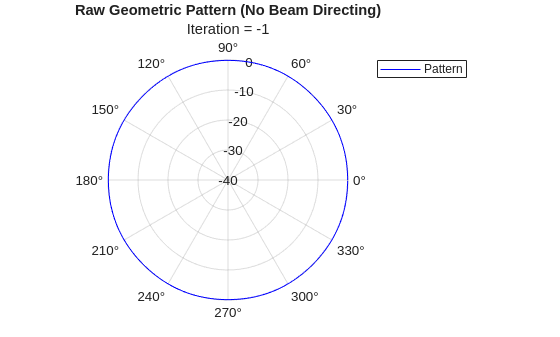

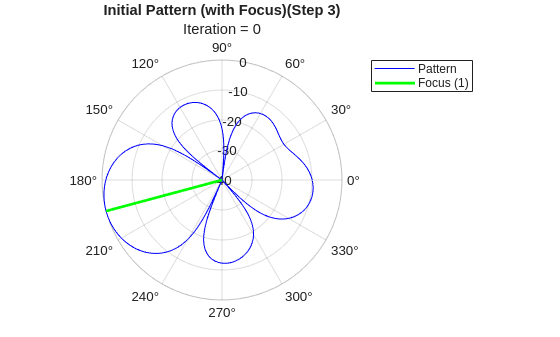

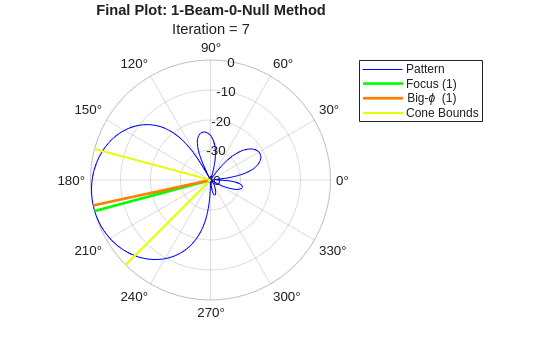

results1 = struct with fields:
                             final_epoch: 7
                         final_iteration: 7
                              total_time: 2.9569
                                       m: 0
                             focus_angle: 3.4034
                         focus_angle_deg: 195
                                cone_rad: 0.5236
                              null_angle: []
                          null_angle_deg: []
                                 F_store: [501×1000 double]
                      max_sidelobe_store: [501×1 double]
                      max_side_phi_store: [501×1 double]
                      main_peakLoc_store: [501×1 double]
                      main_peakVal_store: [501×1 double]
                          main_peak_skew: [-0.0021 -0.0021 -0.0398 -0.0398 0.0105 0.0230 0.0293 0.0168]
    directivity_metric_1_beamwidth_store: [501×1 double]
                          final_function: [0.0711 - 0.0000i 0.0626 + 0.0000i 0.0539 - 0.0000i 0.0451 - 0.


results1 = perturb_method_v22(Max_iter, eps_dB, x, y, ...
    phi_0, ...
    'verbose', false, ...
    'null_phi', null_phi_list, ...
    'show_plots', false, ...
    'show_plot_raw', true, ...
    'show_plot_init', true, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_plots_st16', false, ...
    'show_final_plot',  true, ...
    'cone_rad', cone_rad, ...
    'A_init', [], ...
    'return_funcs', true)





%saveFile = fullfile(saveDir, 'single_angle_1beam.mat');
%save(saveFile, ...
    %'results1', ...
    %'phi_0', ...
    %'eps_dB', ...
    %'Max_iter', ...
    %'null_phi_list', ...
    %'cone_rad');


## Plot Max Sidelobe vs. Epoch Number (1-Beam)

loadFile = fullfile(saveDir, 'single_angle_1beam.mat');
load(loadFile);

%% === Plot Maximum Sidelobe vs. Epoch ===

%{
% Extract the stored sidelobe values
sl_store = results1.max_sidelobe_store;

% Find the last valid entry (not NaN and not -Inf)
valid_mask = ~(isnan(sl_store) | isinf(sl_store));
last_valid = find(valid_mask, 1, 'last');

if isempty(last_valid)
    error('No valid sidelobe entries found in results1.max_sidelobe_store');
end

% Trim to valid portion
sl_valid = sl_store(1:last_valid);

% Epoch axis (1-based index)
epochs = 1:last_valid;

%% --- Make the plot ---
figure;
plot(epochs, sl_valid, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
grid on;

xlabel('Epoch Number');
ylabel('Max Sidelobe Level (dB)');
title('Maximum Sidelobe vs. Epoch');

%ylim([-40 0]);     % Same as polar plot
ylim([eps_dB-1 0]); % See wholw dB range
ylim([-120 0]); % eyeball it
xlim([1 last_valid]);
%}
%% === Plot Maximum Sidelobe, Beamwidth, and Focus Value vs Epoch ===

sl_store = results1.max_sidelobe_store;
bw_store = results1.directivity_metric_1_beamwidth_store;


% Determine valid entries
valid_mask = ~(isnan(sl_store) | isinf(sl_store));
last_valid = find(valid_mask, 1, 'last');

if isempty(last_valid)
    error('No valid sidelobe entries found in results1.max_sidelobe_store');
end

% Trim
sl_valid = sl_store(1:last_valid);
bw_valid = bw_store(1:last_valid);

epochs = 1:last_valid;

% Skip the first 5 points
Nskip = 0;

sl_valid = sl_valid(Nskip+1:end);
bw_valid = bw_valid(Nskip+1:end);
epochs   = epochs(Nskip+1:end);


%% ---- Make plot with dual y-axes ----
figure;

%% LEFT AXIS — Max Sidelobe (dB)
yyaxis left
plot(epochs, sl_valid, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor','b');
%scatter(epochs, sl_valid, 40, 'b', 'filled');
ylabel('Max Sidelobe Level (dB)');
ylim([-100 0]);   % adjust as desired

%% RIGHT AXIS — Beamwidth (radians)
yyaxis right
plot(epochs, bw_valid, '-or', 'LineWidth', 1.5, 'MarkerFaceColor','r');
%scatter(epochs, bw_valid, 40, 'r', 'filled');
ylabel('Beamwidth (radians)');

%% Formatting
xlabel('Epoch Number');
title('Maximum Sidelobe and Beamwidth vs Epoch');
grid on;
xlim([1 last_valid]);

legend({'Max Sidelobe (dB)', 'Beamwidth (rad)'}, 'Location','best');

outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'MaxSide_vs_Epoch_No_Null.fig';
savefig( fullfile(outdir, fname) );
%savefig(gcf, 'MaxSide_vs_Epoch_Null_90deg_cont.fig');

## Plot Max Sidelobe vs. SemiLog Epoch Number (1-Beam)

figure;
semilogx(epochs, sl_valid, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
grid on;

xlabel('Epoch Number (log scale)');
ylabel('Max Sidelobe Level (dB)');
title('Maximum Sidelobe vs. Epoch (Semilog-X)');

ylim([-100 0]);
xlim([1 last_valid]);
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'MaxSide_vs_LogEpoch_No_Null.fig';
savefig( fullfile(outdir, fname) );
%savefig(gcf, 'MaxSide_vs_EpochLog_Null_90deg_cont.fig');


## Plot Function Value in Focus Direction vs. Epoch Number (1-Beam)

## (Optional): Show Plot of Deep Run (1-Beam)

phi_mesh = linspace(0, 2*pi, 1000);
phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate

bw = directivity_met_v2(phi_mesh, results1.final_function, phi_0)

lab_1 = "Final Plot: 1-Beam Method";
%lab_1 = "Final Plot: 1-Beam-1-Null-Const Method";
            % View function graph
            plot_pattern_v5(phi_mesh, ...
                results1.final_function, ...
                'label',lab_1, ...
                'phi_0', phi_0, ...
                'phi_s', [], ...
                'Slobe', [], ...
                'null_phi', [] , ...
                'iter', results1.final_iteration, ...
                'show_plots', true, ...
                'cone_rad', results1.cone_rad, ...
                'bw_edges_right', bw.right_05,...
                'bw_edges_left', bw.left_05,...
                'Big_phi', results1.Big_phi_final);
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'Plot_No_Null_V15.fig';
savefig( fullfile(outdir, fname) );
%savefig(gcf, 'Plot_Null_90deg_cont_1000_Iter.fig');

## Set-up and Run the One-Beam-One-Null version of the Algorythm (Continuous update)

%% Start Function
Max_iter = 2000;
eps_dB = -1000;
phi_0 = deg2rad(0);
null_phi_list = deg2rad([120]);
save_plots = false;
save_final_plot = true;
cone_rad = deg2rad(15);


results3 = perturb_method_v13(Max_iter, eps_dB, x, y, ...
    phi_0, ...
    'show_plots', false, ...
    'verbose', false, ...
    'null_phi', null_phi_list, ...
    'show_final_plot',  false, ...
    'const_null_update', true, ...
    'cone_rad', cone_rad)

%{
results3 = perturb_method_v10D(Max_iter, eps_dB, x, y, phi_0, ...
    'show_final_plot', true, ...
    'null_phi', null_phi_list, ...
    'const_null_update', true, ...
    'compute_HPBW', true, ...
    'compute_FNBW', true, ...
    'print_angle_value_summary', true, ...
    'show_max_peak', true);
%}
saveFile = fullfile(saveDir, 'single_angle_1beam1null_continuous.mat');
save(saveFile, ...
    'results3', ...
    'phi_0', ...
    'eps_dB', ...
    'Max_iter', ...
    'null_phi_list', ...
    'cone_rad');


## Plot Max Sidelobe vs. Epoch Number (1-Beam-1-Null continuous)

loadFile = fullfile(saveDir, 'single_angle_1beam1null_continuous.mat');
load(loadFile);
%% === Plot Maximum Sidelobe vs. Epoch ===

% Extract the stored sidelobe values
sl_store = results3.max_sidelobe_store;

% Find the last valid entry (not NaN and not -Inf)
valid_mask = ~(isnan(sl_store) | isinf(sl_store));
last_valid = find(valid_mask, 1, 'last');

if isempty(last_valid)
    error('No valid sidelobe entries found in results3.max_sidelobe_store');
end

% Trim to valid portion
sl_valid = sl_store(1:last_valid);

% Epoch axis (1-based index)
epochs = 1:last_valid;

%% --- Make the plot ---
figure;
plot(epochs, sl_valid, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
grid on;

xlabel('Epoch Number');
ylabel('Max Sidelobe Level (dB)');
title('Maximum Sidelobe vs. Epoch');

%ylim([-40 0]);     % Same as polar plot
ylim([eps_dB-1 0]); % See wholw dB range
ylim([-100 0]); % eyeball it
xlim([1 last_valid]);
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'MaxSide_vs_Epoch_Null_120deg_Cont.fig';
savefig( fullfile(outdir, fname) );
%savefig(gcf, 'MaxSide_vs_Epoch_Null_120deg_cont.fig');

## Plot Max Sidelobe vs. SemiLog Epoch Number (1-Beam-1-Null continuous)

figure;
semilogx(epochs, sl_valid, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
grid on;

xlabel('Epoch Number (log scale)');
ylabel('Max Sidelobe Level (dB)');
title('Maximum Sidelobe vs. Epoch (Semilog-X)');

ylim([-100 0]);
xlim([1 last_valid]);
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'MaxSide_vs_LogEpoch_Null_120deg_Cont.fig';
savefig( fullfile(outdir, fname) );
%savefig(gcf, 'MaxSide_vs_EpochLog_Null_120deg_cont.fig');


## (Optional): Show Plot of Deep Run (1-Beam-1-Null continuous)

phi_mesh = linspace(0, 2*pi, 1000);
phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate

bw = directivity_met_v2(phi_mesh, results3.final_function, phi_0)

lab_3 = "Final Plot: 1-Beam-1-Null Constant Update Method";
%lab_3 = "Final Plot: 1-Beam-1-Null Constant Update Method";
            % View function graph
            plot_pattern_v4(phi_mesh, ...
                results3.final_function, ...
                'label',lab_3, ...
                'phi_0', phi_0, ...
                'phi_s', [], ...
                'Slobe', [], ...
                'null_phi', null_phi_list , ...
                'iter', results3.final_epoch, ...
                'show_plots', true, ...
                'cone_rad', [], ...
                'bw_edges_right', bw.right_05,...
                'bw_edges_left', bw.left_05,...
                'Big_phi', []);
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'Plot_Null_120deg_Cont.fig';
savefig( fullfile(outdir, fname) );
%savefig(gcf, 'Plot_Null_120deg_cont_1000_Iter.fig');

## Run a sweep over several Focus Angles for (1-Beam) version of the Method:

% because it seems to glitch without this:
saveDir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Saved_Results';


%% Sweep setup
Max_iter = 200;
eps_dB = -20;
%phi_0 = deg2rad(120);
focusAngles_deg = 0:1:360;   % Example sweep
%focusAngles_deg = 0:1:10;   % Example sweep
numAngles = numel(focusAngles_deg);
test_As = ones(numel(x),1);
%phi = linspace(0, 2*pi, 1000);   % MUST match algorithm
phi = linspace(0, 2*pi, 1000+1);
phi(end) = [];   % remove 2π duplicate
nPhi = numel(phi);

F_final_store = NaN(numAngles, nPhi);   % magnitude
max_SL_all   = cell(numAngles, 1);   % cell array of sidelobe vectors
epochs_all   = zeros(numAngles, 1);  % store final epoch count
Big_phi_final = NaN(numAngles, 1); % store final  
right_bound   = NaN(numAngles, 1);  % store right half power beam bound
left_bound   = NaN(numAngles, 1);  % store left half power beam bound
main_peak_skew = zeros(numAngles, 1);  %store results for diffrence between main beam and focus angle
phi0_all_rad = deg2rad(focusAngles_deg);
badAngles = false(numAngles,1); % setup for recording bad angles

%% Sweep loop
for i = 1:numAngles
    try
        phi0 = phi0_all_rad(i);
        
        results = perturb_method_v20(Max_iter, eps_dB, x, y, phi0, ...
            'null_phi', [], ...
            'show_plots', false, ...
            'verbose', false, ...
            'const_null_update', false);

        fprintf('Sweep iter %d OK (%.1f deg)\n', i, focusAngles_deg(i));
        bw = directivity_met_v2(phi, results.final_function, phi0);

        % Store relevant data
        max_SL_all{i} = results.max_sidelobe_store;
        epochs_all(i) = results.final_epoch;
        F_at_focus(i) = results.F_at_phi_0;
        F_final_store(i, :) = results.final_function;
        Big_phi_final(i) = results.Big_phi_final;
        right_bound(i) = bw.right_05;
        left_bound(i) = bw.left_05;
        main_peak_skew(i) = results.main_peak_skew(results.final_epoch);
        % NOTE: Remember to double check the above for correct epoch.

    catch ME
        % ---- Mark as bad ----
        badAngles(i) = true;

        fprintf('*** Sweep iter %d FAILED at %.1f deg ***\n', ...
                 i, focusAngles_deg(i));
        fprintf('%s\n', ME.message);

        % ---- Fill safe defaults ----
        max_SL_all{i}       = NaN;
        epochs_all(i)      = NaN;
        F_at_focus(i)    = NaN;
        F_final_store(i,:) = NaN;
        right_bound(i) = NaN;
        left_bound(i) = NaN;

        continue;   
    end
end

%% Convert cell array → padded matrix

%% Trim each sidelobe vector to its actual recorded length
for i = 1:numAngles
    v = max_SL_all{i};

    % Valid sidelobes are real numbers between 0 and -200 dB
    validIdx = find(v <= 0 & v >= -200);

    if isempty(validIdx)
        max_SL_all{i} = -40;      % fallback
    else
        lastGood = validIdx(end);
        max_SL_all{i} = v(1:lastGood);
    end
end

%% Diagnostic: check sidelobe vector lengths for each angle
%{
fprintf("\n=== Sidelobe vector lengths per angle ===\n");
for i = 1:numAngles
    L = length(max_SL_all{i});
    fprintf("Angle %4.0f deg → length = %d\n", focusAngles_deg(i), length(max_SL_all{i}));
end
%}

% Find longest run (max epoch count)
maxLen = max( cellfun(@length, max_SL_all) );
%fprintf("\nMax sidelobe-store length = %d\n", maxLen);

% Preallocate with NaNs (which surf will skip)
SL_matrix = NaN(numAngles, maxLen);

for i = 1:numAngles
    L = length(max_SL_all{i});
    SL_matrix(i, 1:L) = max_SL_all{i};
end

%% === Extract final-epoch sidelobe for each angle ===
SL_final = zeros(numAngles,1);

for i = 1:numAngles
    v = max_SL_all{i};
    if isempty(v)
        SL_final(i) = NaN;    % should not happen, but safe
    else
        SL_final(i) = v(end); % final epoch sidelobe
    end
end

%% ---- Save sweep data ----
saveFile = fullfile(saveDir, 'sidelobe_sweep_1beam.mat');

save(saveFile, ...
    'SL_matrix', ...
    'max_SL_all', ...
    'SL_final', ...
    'focusAngles_deg', ...
    'epochs_all', ...
    'F_final_store', ...
    'phi', ...
    'badAngles', ...
    'maxLen', ...
    'eps_dB', ...
    'Max_iter', ...
    'right_bound', ...
    'left_bound', ...
    'main_peak_skew', ...
    'Big_phi_final');


## Waterfall Plots of dB vs. Epoch vs. Angle (1-Beam)

%% ---- Load previously saved data ----
% because it seems to glitch without this:
saveDir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Saved_Results';

loadFile = fullfile(saveDir, 'sidelobe_sweep_1beam.mat');
load(loadFile);

%% Waterfall Plot (best for seeing shape of many curves)
figure;
waterfall(SL_matrix);
xlabel('Epoch');
ylabel('Focus Angle Index');
zlabel('Max Sidelobe (dB)');
title('Sidelobe Evolution vs Epoch vs Focus Angle');

%yticks(1:numAngles);
%yticklabels(string(focusAngles_deg));

% Label only every 5 degrees
labelAngles = 0:15:360;

% Convert those angles to row indices in your sweep
labelIdx = arrayfun(@(a) find(focusAngles_deg == a, 1), labelAngles);

% Remove angles that do not exist exactly due to step size
valid = ~cellfun(@isempty, num2cell(labelIdx));
labelAngles = labelAngles(valid);
labelIdx     = labelIdx(valid);

% Apply ticks/labels
yticks(labelIdx);
yticklabels(string(labelAngles));

%% Compute global minimum sidelobe actually achieved (ignoring NaN)
globalMinSL = min(SL_matrix(:), [], 'omitnan');

% A small pad (e.g. 1 dB) so the lowest curve is visible
zlim([globalMinSL - 1, 0]); %try to set at just below dB threshold
xlim([0 maxLen+1]);
ylim([0 numAngles])
grid on;

ax = gca;
chart = ax.Children(1);
datatip(chart,9,360,-11.09);
view(45, 30); %Classic "from front-right"
view(30, 50); %More overhead (good for reading labels)
view(80, 25); %More from the side (good for depth)
view(100, 20); %Show epoch axis clearly
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = '3D_Plot_No_Null.fig';
savefig( fullfile(outdir, fname) );

## Plot 2D Limit slice: Angle vs Skew  (1-Beam)

%% === Plot 2D slice: Angle vs Final Sidelobe ===
figure;
plot(focusAngles_deg, rad2deg(main_peak_skew), '-ob', 'LineWidth', 1.5, 'MarkerFaceColor','b');
grid on;

xlabel('Focus Angle (deg)');
xlim([-10 370]);
ylabel('Angle Error');
ylim([min(rad2deg(main_peak_skew)) - 1, max(rad2deg(main_peak_skew)) + 1]);
%ylim([(-5) - 1, (5) + 1]);
title('Main Peak Deviance');
subtitle('Angle Difference between Main Peak Max and Focus Direction vs. Sweep Angle');
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'Skew_Behaviour_No_Null.fig';
savefig( fullfile(outdir, fname) );

## Plot 2D Limit slice: Angle vs Final Sidelobe  (1-Beam)

%% === Plot 2D slice: Angle vs Final Sidelobe ===
figure;
plot(focusAngles_deg, SL_final, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor','b');
grid on;

xlabel('Focus Angle (deg)');
xlim([-10 370]);
ylabel('Final Max Sidelobe (dB)');
ylim([globalMinSL - 1, 0]);
title('Tail Behaviour');
subtitle('Final Max Sidelobe vs. Sweep Angle');
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'Tail_Behaviour_No_Null.fig';
savefig( fullfile(outdir, fname) );

## Plot: Angle vs Final Sidelobe vs Focus Magnitude  (1-Beam)

figure;
scatter3(focusAngles_deg, SL_final, F_at_focus, 40, F_at_focus, 'filled');

xlabel('Focus Angle (deg)');
ylabel('Final Sidelobe (dB)');
zlabel('|F(\phi_0)|  (Magnitude)');
title('Final Sidelobe vs Focus Magnitude vs Focus Angle');

grid on;
view(40, 30);
colorbar;

## Run a sweep over several Focus Angles for (1-Beam-1-Null-Constant Update) version of the Method:

%% Sweep setup
Max_iter = 200;
eps_dB = -1000;
%phi_0 = deg2rad(120);
focusAngles_deg = 0:1:360;   % Example sweep
numAngles = numel(focusAngles_deg);

max_SL_all   = cell(numAngles, 1);   % cell array of sidelobe vectors
epochs_all   = zeros(numAngles, 1);  % store final epoch count
phi0_all_rad = deg2rad(focusAngles_deg);

%% Sweep loop
for i = 1:numAngles
    phi0 = phi0_all_rad(i);
    results = perturb_method_v15(Max_iter, eps_dB, x, y, phi0, ...
        'null_phi', [0], ...
        'show_plots', false, ...
        'verbose', false, ...
        'const_null_update', true);
    % Store relevant data
    max_SL_all{i} = results.max_sidelobe_store;
    epochs_all(i) = results.final_epoch;
    F_at_focus(i) = results.F_at_phi_0;
end

%% Convert cell array → padded matrix

%% Trim each sidelobe vector to its actual recorded length
for i = 1:numAngles
    v = max_SL_all{i};

    % Valid sidelobes are real numbers between 0 and -200 dB
    validIdx = find(v <= 0 & v >= -200);

    if isempty(validIdx)
        max_SL_all{i} = -40;      % fallback
    else
        lastGood = validIdx(end);
        max_SL_all{i} = v(1:lastGood);
    end
end

%% Diagnostic: check sidelobe vector lengths for each angle
%{
fprintf("\n=== Sidelobe vector lengths per angle ===\n");
for i = 1:numAngles
    L = length(max_SL_all{i});
    fprintf("Angle %4.0f deg → length = %d\n", focusAngles_deg(i), length(max_SL_all{i}));
end
%}

% Find longest run (max epoch count)
maxLen = max( cellfun(@length, max_SL_all) );
%fprintf("\nMax sidelobe-store length = %d\n", maxLen);

% Preallocate with NaNs (which surf will skip)
SL_matrix = NaN(numAngles, maxLen);

for i = 1:numAngles
    L = length(max_SL_all{i});
    SL_matrix(i, 1:L) = max_SL_all{i};
end

%% === Extract final-epoch sidelobe for each angle ===
SL_final = zeros(numAngles,1);

for i = 1:numAngles
    v = max_SL_all{i};
    if isempty(v)
        SL_final(i) = NaN;    % should not happen, but safe
    else
        SL_final(i) = v(end); % final epoch sidelobe
    end
end

%% ---- Save sweep data ----
saveFile = fullfile(saveDir, 'sidelobe_sweep_1beam1nullconstant.mat');

save(saveFile, ...
    'SL_matrix', ...
    'max_SL_all', ...
    'SL_final', ...
    'focusAngles_deg', ...
    'epochs_all', ...
    'maxLen', ...
    'eps_dB', ...
    'Max_iter');

## Waterfall Plots of dB vs. Epoch vs. Angle (1-Beam-1-Null-Constant Update)

%% ---- Load previously saved data ----
loadFile = fullfile(saveDir, 'sidelobe_sweep_1beam1nullconstant.mat');
load(loadFile);

%% Waterfall Plot (best for seeing shape of many curves)
figure;
waterfall(SL_matrix);
xlabel('Epoch');
ylabel('Focus Angle Index');
zlabel('Max Sidelobe (dB)');
title('Sidelobe Evolution vs Epoch vs Focus Angle');

%yticks(1:numAngles);
%yticklabels(string(focusAngles_deg));

% Label only every 5 degrees
labelAngles = 0:15:360;

% Convert those angles to row indices in your sweep
labelIdx = arrayfun(@(a) find(focusAngles_deg == a, 1), labelAngles);

% Remove angles that do not exist exactly due to step size
valid = ~cellfun(@isempty, num2cell(labelIdx));
labelAngles = labelAngles(valid);
labelIdx     = labelIdx(valid);

% Apply ticks/labels
yticks(labelIdx);
yticklabels(string(labelAngles));

%% Compute global minimum sidelobe actually achieved (ignoring NaN)
globalMinSL = min(SL_matrix(:), [], 'omitnan');

% A small pad (e.g. 1 dB) so the lowest curve is visible
zlim([globalMinSL - 1, 0]); %try to set at just below dB threshold
xlim([0 maxLen+1]);
ylim([0 numAngles])
grid on;
 
ax = gca;
chart = ax.Children(1);
datatip(chart,9,360,-11.09);
view(45, 30); %Classic "from front-right"
%view(30, 50); %More overhead (good for reading labels)
%view(80, 25); %More from the side (good for depth)
%view(100, 20); %Show epoch axis clearly
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = '3D_Plot_0Deg_Null_Cont.fig';
savefig( fullfile(outdir, fname) );

## Plot 2D Limit slice: Angle vs Final Sidelobe (1-Beam-1-Null-Constant Update)

%% === Plot 2D slice: Angle vs Final Sidelobe ===
figure;
plot(focusAngles_deg, SL_final, '-ob', 'LineWidth', 1.5, 'MarkerFaceColor','b');
grid on;

xlabel('Focus Angle (deg)');
xlim([-10 370]);
ylabel('Final Max Sidelobe (dB)');
ylim([globalMinSL - 1, 0]);
title('Tail Behaviour');
subtitle('Final Max Sidelobe vs. Sweep Angle');
outdir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Plot_Saves';
fname = 'Tail_Behaviour_0Deg_Null_Cont.fig';
savefig( fullfile(outdir, fname) );

## Plot: Angle vs Final Sidelobe vs Focus Magnitude  (1-Beam-1-Null-Constant Update)

figure;
scatter3(focusAngles_deg, SL_final, F_at_focus, 40, F_at_focus, 'filled');

xlabel('Focus Angle (deg)');
ylabel('Final Sidelobe (dB)');
zlabel('|F(\phi_0)|  (Magnitude)');
title('Final Sidelobe vs Focus Magnitude vs Focus Angle');

grid on;
view(40, 30);
colorbar;

## Plot: 2-Beam Function (Mosier Version)

phi_0_1 = deg2rad(5);
phi_0_2 = deg2rad(125);
phi_0_set = [phi_0_1 phi_0_2];
Max_iter = 200;
eps_dB = -30;
null_phi_list_1 = phi_0_2;
null_phi_list_2 = phi_0_1;
N = numel(x);
save_plots = false;

results_2A = perturb_method_v18(Max_iter, eps_dB, x, y, ...
    phi_0_1, ...
    'show_plots', false, ...
    'verbose', false, ...
    'null_phi', null_phi_list_1, ...
    'show_final_plot',  true, ...
    'const_null_update', false)
results_2B = perturb_method_v18(Max_iter, eps_dB, x, y, ...
    phi_0_2, ...
    'show_plots', false, ...
    'verbose', false, ...
    'null_phi', null_phi_list_2, ...
    'show_final_plot',  true, ...
    'const_null_update', false)
% Add the two plots together to get 2-beam plot
%test_F_total = results_2A.final_function + results_2B.final_function;
test_F_total = (N*results_2A.final_function/max(results_2A.final_function)) ...
+ (N*results_2B.final_function/max(results_2B.final_function));

phi_mesh = linspace(0, 2*pi, 1000);   % MUST match algorithm
phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate
bw1 = directivity_met_v2(phi_mesh, test_F_total, phi_0_1);
bw2 = directivity_met_v2(phi_mesh, test_F_total, phi_0_2);
lab_1 = "Final Plot: Basic (Superposition) 2-Beam";
%lab_1 = "Final Plot: Mosier 2-Beam";
            % View function graph
            plot_pattern_v5(phi_mesh, ...
                abs(test_F_total), ...
                'label',lab_1, ...
                'phi_0', phi_0_set, ...
                'show_plots', true, ...
                'cone_rad', [], ...
                'bw_edges_right', [bw1.right_05 bw2.right_05],...
                'bw_edges_left', [bw1.left_05 bw2.left_05],...                
                'iter', max(results_2A.final_iteration, results_2B.final_iteration));


Run a (prototype) sweep over several Focus Angles for (Mosier 2-Beam) version of the Method:

%% ================================================================
%% BLOCK 1 — Sweep + SAVE ONLY (no plots, no video)
%% ================================================================
% Requirements in workspace:
%   x, y
% Functions on path:
%   perturb_method_v17, directivity_met_v2
%
% Output:
%   outdir/
%     config.mat
%     sweep_summary.mat
%     step_0001_phi1_000.mat   (etc)

assert(exist('x','var')==1 && exist('y','var')==1, 'x and y must exist in workspace.');

% IMPORTANT: clear any previous run variables that could conflict
clear all_results cfg S smallA smallB bw1 bw2 results_2A results_2B

% ---- Sweep controls ----
phi_step_deg  = 5;              % try 5, 10, etc. (later can do 1)
phi1_deg_list = 0:phi_step_deg:359;
delta_deg     = 120;            % fixed offset

% ---- Algorithm controls ----
Max_iter = 1000;                % consider lowering if each call is expensive
eps_dB   = -20;

% ---- Pattern mesh ----
phi_mesh = linspace(0, 2*pi, 1000);
phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate
N = numel(x);

% ---- Output folder (Windows-safe) ----
timestamp = datestr(now,'yyyy-mm-dd_HHMMSS');
outdir = fullfile(pwd, ['two_beam_sweep_' timestamp]);
if ~exist(outdir,'dir'), mkdir(outdir); end

% Save config once (fast)
save(fullfile(outdir,'config.mat'), ...
     'phi_step_deg','phi1_deg_list','delta_deg','Max_iter','eps_dB','phi_mesh','N', '-v7');

% ---- Preallocate summary struct ROBUSTLY ----
numK = numel(phi1_deg_list);
tmpl = struct( ...
    'k', [], ...
    'phi0_1_deg', [], 'phi0_2_deg', [], ...
    'phi0_1_rad', [], 'phi0_2_rad', [], ...
    'iterA', [], 'iterB', [], ...
    'bw1_left_05', [], 'bw1_right_05', [], ...
    'bw2_left_05', [], 'bw2_right_05', [], ...
    'maxF', [] );
all_results = repmat(tmpl, numK, 1);

fprintf('Saving sweep to:\n  %s\n', outdir);
tSweep = tic;

for k = 1:numK
    phi0_1_deg = phi1_deg_list(k);
    phi0_2_deg = mod(phi0_1_deg + delta_deg, 360);

    phi_0_1 = deg2rad(phi0_1_deg);
    phi_0_2 = deg2rad(phi0_2_deg);

    % Null lists (your convention)
    null_phi_list_1 = phi_0_2;
    null_phi_list_2 = phi_0_1;

    % ---- Run two optimizations (expensive part) ----
    t0 = tic;
    results_2A = perturb_method_v17(Max_iter, eps_dB, x, y, ...
        phi_0_1, ...
        'show_plots', false, ...
        'verbose', false, ...
        'null_phi', null_phi_list_1, ...
        'show_final_plot', false, ...
        'const_null_update', false);

    results_2B = perturb_method_v17(Max_iter, eps_dB, x, y, ...
        phi_0_2, ...
        'show_plots', false, ...
        'verbose', false, ...
        'null_phi', null_phi_list_2, ...
        'show_final_plot', false, ...
        'const_null_update', false);
    tOpt = toc(t0);

    % ---- Combine patterns (your normalization) ----
    fa = results_2A.final_function(:).';   % row
    fb = results_2B.final_function(:).';   % row

    maxA = max(fa); if maxA == 0, maxA = 1; end
    maxB = max(fb); if maxB == 0, maxB = 1; end

    F_total = (N * fa / maxA) + (N * fb / maxB);

    % ---- Metrics ----
    bw1 = directivity_met_v2(phi_mesh, F_total, phi_0_1);
    bw2 = directivity_met_v2(phi_mesh, F_total, phi_0_2);

    % ---- Save a SMALL per-step file (FAST) ----
    % Save only what's needed for video/analysis; do NOT save huge result histories.
    iterA = results_2A.final_iteration;
    iterB = results_2B.final_iteration;

    bw1_left_05  = bw1.left_05;
    bw1_right_05 = bw1.right_05;
    bw2_left_05  = bw2.left_05;
    bw2_right_05 = bw2.right_05;

    stepfile = fullfile(outdir, sprintf('step_%04d_phi1_%03d.mat', k, phi0_1_deg));
    save(stepfile, ...
        'k', 'phi0_1_deg','phi0_2_deg','phi_0_1','phi_0_2', ...
        'iterA','iterB', ...
        'F_total', ...
        'bw1_left_05','bw1_right_05','bw2_left_05','bw2_right_05', ...
        '-v7');

    % ---- Store light summary ----
    all_results(k).k           = k;
    all_results(k).phi0_1_deg  = phi0_1_deg;
    all_results(k).phi0_2_deg  = phi0_2_deg;
    all_results(k).phi0_1_rad  = phi_0_1;
    all_results(k).phi0_2_rad  = phi_0_2;
    all_results(k).iterA       = iterA;
    all_results(k).iterB       = iterB;
    all_results(k).bw1_left_05 = bw1_left_05;
    all_results(k).bw1_right_05= bw1_right_05;
    all_results(k).bw2_left_05 = bw2_left_05;
    all_results(k).bw2_right_05= bw2_right_05;
    all_results(k).maxF        = max(abs(F_total));

%    fprintf('k=%3d/%3d | phi1=%3d°, phi2=%3d° | opt=%.2fs\n', ...
%        k, numK, phi0_1_deg, phi0_2_deg, tOpt);
end

save(fullfile(outdir,'sweep_summary.mat'), 'all_results', '-v7');

fprintf('\nDONE sweep.\nTotal time: %.2f min\nFolder:\n  %s\n', toc(tSweep)/60, outdir);



%% ================================================================
%% BLOCK 2 — LOAD saved steps + BUILD VIDEO (plots only here)
%% ================================================================
% Set outdir to the folder created by Block 1.
% Example:
%   outdir = "C:\Users\you\Documents\MATLAB\two_beam_sweep_2026-02-11_203012";

cfg = load(fullfile(outdir,'config.mat'));
phi_mesh      = cfg.phi_mesh;
phi1_deg_list = cfg.phi1_deg_list;

deg_mesh = rad2deg(phi_mesh);   % precompute once

% ---- Video setup ----
vidfile = fullfile(outdir, 'two_beam_sweep.mp4');
v = VideoWriter(vidfile, 'MPEG-4');
v.FrameRate = 20;
open(v);

% ---- Lightweight plot (fast + reliable) ----
fig = figure('Color','w');
set(fig,'Position',[100 100 900 700]);

numK = numel(phi1_deg_list);
tVid = tic;

for k = 1:numK
    phi0_1_deg = phi1_deg_list(k);
    stepfile = fullfile(outdir, sprintf('step_%04d_phi1_%03d.mat', k, phi0_1_deg));
    S = load(stepfile);  % loads F_total, bw edges, angles, etc.

    clf(fig);

    plot(deg_mesh, abs(S.F_total), 'LineWidth', 1);
    grid on; xlim([0 360]);
    xlabel('Angle (deg)');
    ylabel('|F_{total}|');
    title(sprintf('\\phi_{0,1}=%d^\\circ, \\phi_{0,2}=%d^\\circ | iterA=%d, iterB=%d', ...
                  S.phi0_1_deg, S.phi0_2_deg, S.iterA, S.iterB));

    hold on;
    yl = ylim;
    xline(S.phi0_1_deg, '--'); xline(S.phi0_2_deg, '--');
    % Mark -3dB (0.5) beamwidth edges if you like:
    xline(rad2deg(S.bw1_left_05),  ':');
    xline(rad2deg(S.bw1_right_05), ':');
    xline(rad2deg(S.bw2_left_05),  ':');
    xline(rad2deg(S.bw2_right_05), ':');
    ylim(yl);
    hold off;

    drawnow;
    writeVideo(v, getframe(fig));

    if mod(k,10)==0 || k==numK
        fprintf('Video frame %3d/%3d\n', k, numK);
    end
end

close(v);

fprintf('\nDONE video.\nTime: %.2f sec\nMovie:\n  %s\n', toc(tVid), vidfile);


%% ================================================================
%% BLOCK 2 — LOAD saved steps + BUILD VIDEO (POLAR, dB floor at -40)
%% ================================================================
% Set outdir to the folder created by Block 1.
% Example:
%   outdir = "C:\Users\you\Documents\MATLAB\two_beam_sweep_2026-02-11_203012";

cfg = load(fullfile(outdir,'config.mat'));
phi_mesh      = cfg.phi_mesh;        % theta in radians
phi1_deg_list = cfg.phi1_deg_list;

% ---- dB settings ----
db_floor = -40;                      % origin corresponds to -40 dB
rmax     = -db_floor;                % 40

% ---- Video setup ----
vidfile = fullfile(outdir, 'two_beam_sweep_polar_db.mp4');
v = VideoWriter(vidfile, 'MPEG-4');
v.FrameRate = 20;
open(v);

fig = figure('Color','w');
set(fig,'Position',[100 100 900 700]);

numK = numel(phi1_deg_list);

for k = 1:numK
    phi0_1_deg = phi1_deg_list(k);
    stepfile = fullfile(outdir, sprintf('step_%04d_phi1_%03d.mat', k, phi0_1_deg));
    S = load(stepfile);

    mag = abs(S.F_total);
    mag_max = max(mag);
    if mag_max == 0, mag_max = 1; end

    % Relative dB (peak = 0 dB), floored at db_floor
    mag_db = 20*log10(mag / mag_max);
    mag_db = max(mag_db, db_floor);

    % Map: db_floor -> 0 radius, 0 dB -> rmax
    r = mag_db - db_floor;

    clf(fig);

    % Create polar axes explicitly (more control)
    pax = polaraxes(fig);
    polarplot(pax, phi_mesh, r, 'LineWidth', 1);
    pax.RLim = [0 rmax];
    pax.ThetaLim = [0 360];

    % Radius ticks labeled in dB (so you SEE -40 at the origin)
    rticks = 0:10:rmax;                           % 0..40
    pax.RTick = rticks;
    pax.RTickLabel = string((db_floor:10:0));     % -40..0

    title(pax, sprintf('\\phi_{0,1}=%d^\\circ, \\phi_{0,2}=%d^\\circ | iterA=%d, iterB=%d', ...
        S.phi0_1_deg, S.phi0_2_deg, S.iterA, S.iterB));

    hold(pax, 'on');

    % Mark beam centers as radial lines
    th1 = deg2rad(S.phi0_1_deg);
    th2 = deg2rad(S.phi0_2_deg);
    polarplot(pax, [th1 th1], [0 rmax], '--', 'LineWidth', 1);
    polarplot(pax, [th2 th2], [0 rmax], '--', 'LineWidth', 1);

    % Optional: mark -3 dB beamwidth edges if your bw*_left/right are radians
    polarplot(pax, [S.bw1_left_05  S.bw1_left_05 ], [0 rmax], ':');
    polarplot(pax, [S.bw1_right_05 S.bw1_right_05], [0 rmax], ':');
    polarplot(pax, [S.bw2_left_05  S.bw2_left_05 ], [0 rmax], ':');
    polarplot(pax, [S.bw2_right_05 S.bw2_right_05], [0 rmax], ':');

    hold(pax, 'off');

    drawnow;
    writeVideo(v, getframe(fig));

    if mod(k,10)==0 || k==numK
        fprintf('Video frame %3d/%3d\n', k, numK);
    end
end

close(v);
fprintf('\nDONE polar-dB video.\nMovie:\n  %s\n', vidfile);

## Plot: 2-Beam Function (Advanceds Version)

phi_0_1 = deg2rad(0);
phi_0_2 = deg2rad(210);
phi_0_set = [phi_0_1 phi_0_2];
results_2b = perturb_method_2_beam_v3(x, y, phi_0_1, phi_0_2)
bw1 = directivity_met_v2(phi_mesh, results_2b.final_function, phi_0_1);
bw2 = directivity_met_v2(phi_mesh, results_2b.final_function, phi_0_2);
phi_mesh = linspace(0, 2*pi, 1000);
phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate
lab_1 = "Initial Plot: Advanced 2-Beam Method";
%lab_1 = "Final Plot: PROTOTYPE New Basic 2-Beam";
%lab_1 = "Final Plot: 1-Beam-1-Null-Const Method";
            % View function graph
            plot_pattern_v5(phi_mesh, ...
                results_2b.final_function, ...
                'label',lab_1, ...
                'phi_0', phi_0_set, ...
                'show_plots', true, ...
                'cone_rad', [], ...
                'bw_edges_right', [bw1.right_05 bw2.right_05],...
                'bw_edges_left', [bw1.left_05 bw2.left_05],...
                'iter', 1);
                %'Big_phi', [results_2b.Big_phi_final_1]);

## Prototype Functions

%% Start Function
Max_iter = 200;
eps_dB = -20;
phi_0 = deg2rad(0);
null_phi_list = deg2rad([120]);
save_plots = false;
save_final_plot = true;
cone_rad = deg2rad(30);
cone_rad_goal = deg2rad(45);

%{
resultsPROTO = perturb_method_v14(Max_iter, eps_dB, x, y, ...
    phi_0, ...
    'show_plots', false, ...
    'verbose', false, ...
    'null_phi', null_phi_list, ...
    'show_final_plot',  false, ...
    'const_null_update', true, ...
    'cone_rad', cone_rad, ...
    'cone_rad_goal', cone_rad_goal)
%}

resultsPROTO = perturb_method_2_beam_v3(x, y, phi_0_1, phi_0_2, ...
    'show_plots', false, ...
    'verbose', false, ...
    'show_plot_init', true)

phi_mesh = linspace(0, 2*pi, 1000);
phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate

%bw = directivity_met_v2(phi_mesh, resultsPROTO.final_function, phi_0);
bw1 = directivity_met_v2(phi_mesh, resultsPROTO.final_function, phi_0_1);
bw2 = directivity_met_v2(phi_mesh, resultsPROTO.final_function, phi_0_2);

lab_1 = "Final Plot: Advanced 2-Beam Method";
%lab_1 = "Final Plot: PROTOTYPE 1-Beam-0-Null";
%lab_1 = "Final Plot: 1-Beam-1-Null-Const Method";
            % View function graph
            plot_pattern_v5(phi_mesh, ...
                resultsPROTO.final_function, ...
                'label',lab_1, ...
                'phi_0', phi_0_set, ...
                'phi_s', [], ...
                'Slobe', [], ...
                'iter', resultsPROTO.final_iteration, ...
                'show_plots', true, ...
                'cone_rad', [], ...
                'bw_edges_right', [bw1.right_05 bw2.right_05],...
                'bw_edges_left', [bw1.left_05 bw2.left_05],...
                'Big_phi', []);


SCRATCH

    %% ---- Build the F2D Function ----
    function F = F2d(phi_loc, A_loc, x_loc, y_loc, delta_loc, k0_loc)
    % F2d  Compute the 2D array factor of an antenna array.
    % Inputs:
    %   phi_loc   - vector of azimuth angles (radians)
    %   A_loc     - Nx1 complex vector of element amplitudes
    %   x_loc, y_loc  - Nx1 vectors of element coordinates (meters)
    %   delta_loc - Nx1 phase offsets (radians). If empty, assumed zeros.
    %   k0_loc    - wavenumber = 2*pi/lambda
    % Output:
    %   F     - complex field pattern evaluated at each phi
        if nargin < 6   % error handling
            error('F2d: need phi, A, x, y, delta, k0');
        end
        % Ensure column vectors
        A_loc = A_loc(:);
        x_loc = x_loc(:);
        y_loc = y_loc(:);
        if isempty(delta_loc) % Initialize zero delta if needed
            delta_loc = zeros(size(A_loc));
        else
            delta_loc = delta_loc(:);
        end
        phi_loc = phi_loc(:).';  % 1xM row vector for broadcasting
        % phase term for each element and angle: N x M phase matrix
        phase = k0_loc * (x_loc * cos(phi_loc) + y_loc * sin(phi_loc)) + delta_loc;        
        F = A_loc.' * exp(1j * phase);  % 1 x M
    end
            
A_store = results1.A_store;
delta_store = results1.delta_store;
k0     = 2*pi / lambda;
A_eff = zeros(size(A_store{1}));

for k = 1:length(A_store)
    A_eff = A_eff + A_store{k} .* exp(1j * delta_store{k});
end

delta_eff = zeros(size(A_eff)); % already absorbed

F_eff = F2d(phi_mesh, results1.A_eff, x, y, results1.delta_eff, k0);

max(abs(F_eff - results1.final_function))   % should be very small

bw1 = directivity_met_v2(phi_mesh, results1.final_function, phi_0);
%phi_mesh = linspace(0, 2*pi, 1000+1);
%phi_mesh(end) = [];   % remove 2π duplicate
lab_1 = "Test Plot: Rebuilt Final 1-Beam Method";
%lab_1 = "Final Plot: PROTOTYPE New Basic 2-Beam";
%lab_1 = "Final Plot: 1-Beam-1-Null-Const Method";
            % View function graph
            plot_pattern_v5(phi_mesh, ...
                F_eff, ...
                'label',lab_1, ...
                'phi_0', phi_0, ...
                'show_plots', true, ...
                'cone_rad', [], ...
                'bw_edges_right', [bw1.right_05],...
                'bw_edges_left', [bw1.left_05],...
                'iter', 1);

            plot_pattern_v5(phi_mesh, ...
                results1.final_function, ...
                'label',lab_1, ...
                'phi_0', phi_0, ...
                'show_plots', true, ...
                'cone_rad', [], ...
                'bw_edges_right', [bw1.right_05],...
                'bw_edges_left', [bw1.left_05],...
                'iter', 1);

MORE SCRATCH

phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate
            
results1 = perturb_method_v21(Max_iter, eps_dB, x, y, ...
    phi_0, ...
    'verbose', false, ...
    'null_phi', null_phi_list, ...
    'show_plots', false, ...
    'show_plot_raw', false, ...
    'show_plot_init', false, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_plots_st16', false, ...
    'show_final_plot',  false, ...
    'cone_rad', cone_rad, ...
    'A_init', [], ...
    'return_funcs', true) 

gain_calc(results1.F_store(1,:), phi_mesh, phi_0)